%  Number of Files
numFiles = length(audioFiles);
fixedLength = 16000; % number of samples per file
allWaveforms = [];

%  Loop Through Audio Files
for i = 1:numFiles
    fileName = audioFiles(i);
    
    % Load Audio File
    [y, Fs] = audioread(fileName);
    
    if size(y, 2) > 1
        y = mean(y, 2);
    end
    
    % Resample or Trim to Fixed Length
    if length(y) > fixedLength
        y = y(1:fixedLength); % Trim excess samples
    elseif length(y) < fixedLength
        y = [y; zeros(fixedLength - length(y), 1)]; % Zero-pad if too short
    end
    
    % Normalize Waveform
    y = (y - mean(y)) / std(y);
    
    % Store Processed Waveform
    allWaveforms = [allWaveforms; y'];
end

%  Convert to Numeric Matrix for Autoencoder (Samples × Features)
waveformData = reshape(allWaveforms, numFiles, fixedLength);

disp("Final Waveform Dataset Shape:");

Final Waveform Dataset Shape:


disp(size(waveformData)); % Should be [NumFiles, FixedLength]

          15       16000



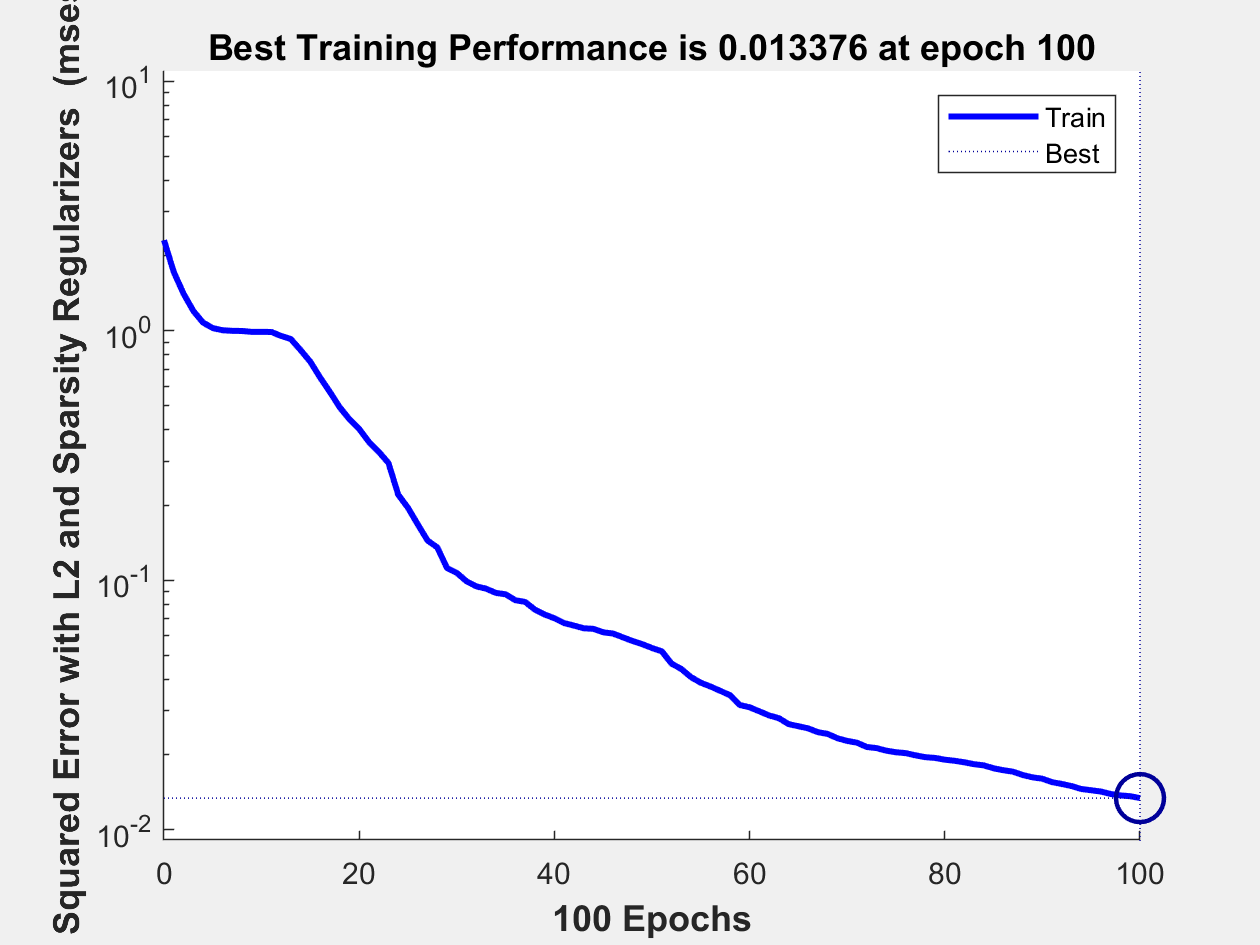

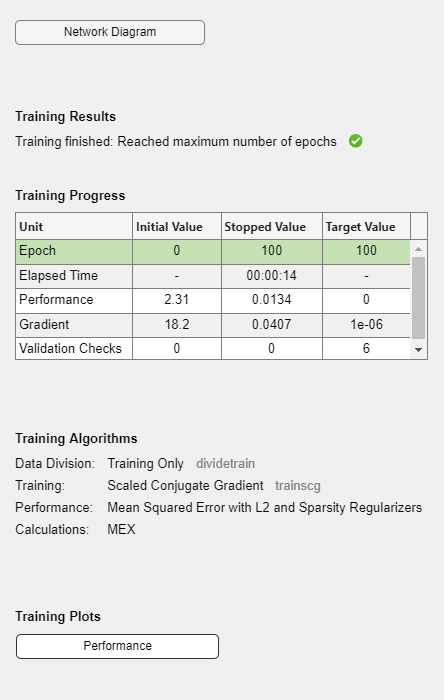




%  Train Second Autoencoder on Encoded Features
hiddenSize2 = 32; % Second layer captures more abstract patterns
autoenc2 = trainAutoencoder(waveformData, hiddenSize2, ...
    'MaxEpochs', 100,...
    'EncoderTransferFunction','satlin',...
     'DecoderTransferFunction','purelin',...
    'L2WeightRegularization', 0.0001, ...
    'SparsityRegularization', 1, ...
    'SparsityProportion', 0.1, ...
    'ScaleData', true);